clear all;
clc;

## Loading data

addpath("data");

> In path (line 109)
  In addpath (line 96)
  In addpath (

% Loading data.
collect_time_table;

**Setup Model Parameters**

% Precentage of data used as training data.
modelParameter.trainingSize = 0.7;
% Index of RESPONSE variable in data array.
modelParameter.responseIndex = 1;

## Initial visualization

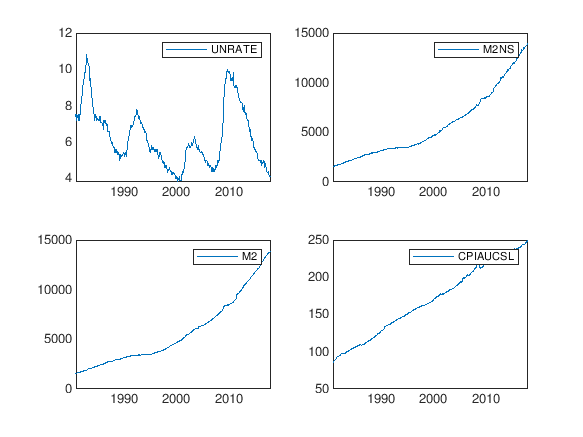

num_plot = length(names);
plot_size = ceil(sqrt(num_plot));
for i = 1:num_plot
    subplot(plot_size, plot_size, i);
    plot(data_tt.DATE, (data_ar(i, :)), 'LineWidth', 1.2);
    legend(names{i});
end

## Creating data sets

totalSize = height(data_tt);

numTimeStepsTrain = floor(...
    totalSize * modelParameter.trainingSize);

% Training Data for X.
x_ar = data_ar;
y_ar = data_tt.UNRATE';  % Response Data Y.

% Indexing, DATA(dataIndex, timeStep)

XTrain = x_ar(:, ...
    (1:numTimeStepsTrain));

YTrain = y_ar(1, ...
    (2:numTimeStepsTrain + 1));

XTest = x_ar(:, ...
    (numTimeStepsTrain + 1: end - 1));

YTest = y_ar(1, ...
    numTimeStepsTrain + 2: end);

## Standardize data (Mean Normalization)

mu = mean(XTrain, 2);
sig = std(XTrain, 0, 2);

XTrain = (XTrain - mu) ./ sig;
XTest = (XTest - mu) ./ sig;

YTrain = (YTrain - mean(YTrain)) ./ std(YTrain);


$$x_i := \frac{x_i - \overline{x}}{s_x}$$


## Setup neural network

inputSize = 4;
numResponses = 1;

numHiddenUnits.lstm1 = 64;
numHiddenUnits.lstm2 = 32;
numHiddenUnits.fc1 = 128;
numHiddenUnits.fc2 = 32;

layers = [...
	sequenceInputLayer(inputSize, "Name", "Input layer")
	lstmLayer(numHiddenUnits.lstm1, "Name", "LSTM layer 1")
	lstmLayer(numHiddenUnits.lstm2, "Name", "LSTM layer 2")
	fullyConnectedLayer(numHiddenUnits.fc1, "Name", "FC layer 1")
	fullyConnectedLayer(numResponses, "Name", "Output layer")
	regressionLayer
	];

layers2 = [...
	sequenceInputLayer(inputSize, 'Name', 'Input layer')
	lstmLayer(numHiddenUnits.lstm1, 'Name', 'LSTM layer 1')
	fullyConnectedLayer(numHiddenUnits.fc1, 'Name', 'FC layer 1')
        fullyConnectedLayer(numHiddenUnits.fc2, 'Name', 'FC layer 2')
	fullyConnectedLayer(numResponses, 'Name', 'Output layer')
	regressionLayer
	];

Undefined function or variable 'Name'.


opts = trainingOptions(...
	"adam",...
	"MaxEpochs", 3500, ...
	"GradientThreshold", 100, ...
	"InitialLearnRate", 0.05, ...
	"LearnRateSchedule", "piecewise", ...
	"LearnRateDropPeriod", 500, ...
	"LearnRateDropFactor", 0.5, ...
        "MiniBatchSize", 72, ...
	"Verbose", 1, ...
	"Plot", "training-progress");

## Training

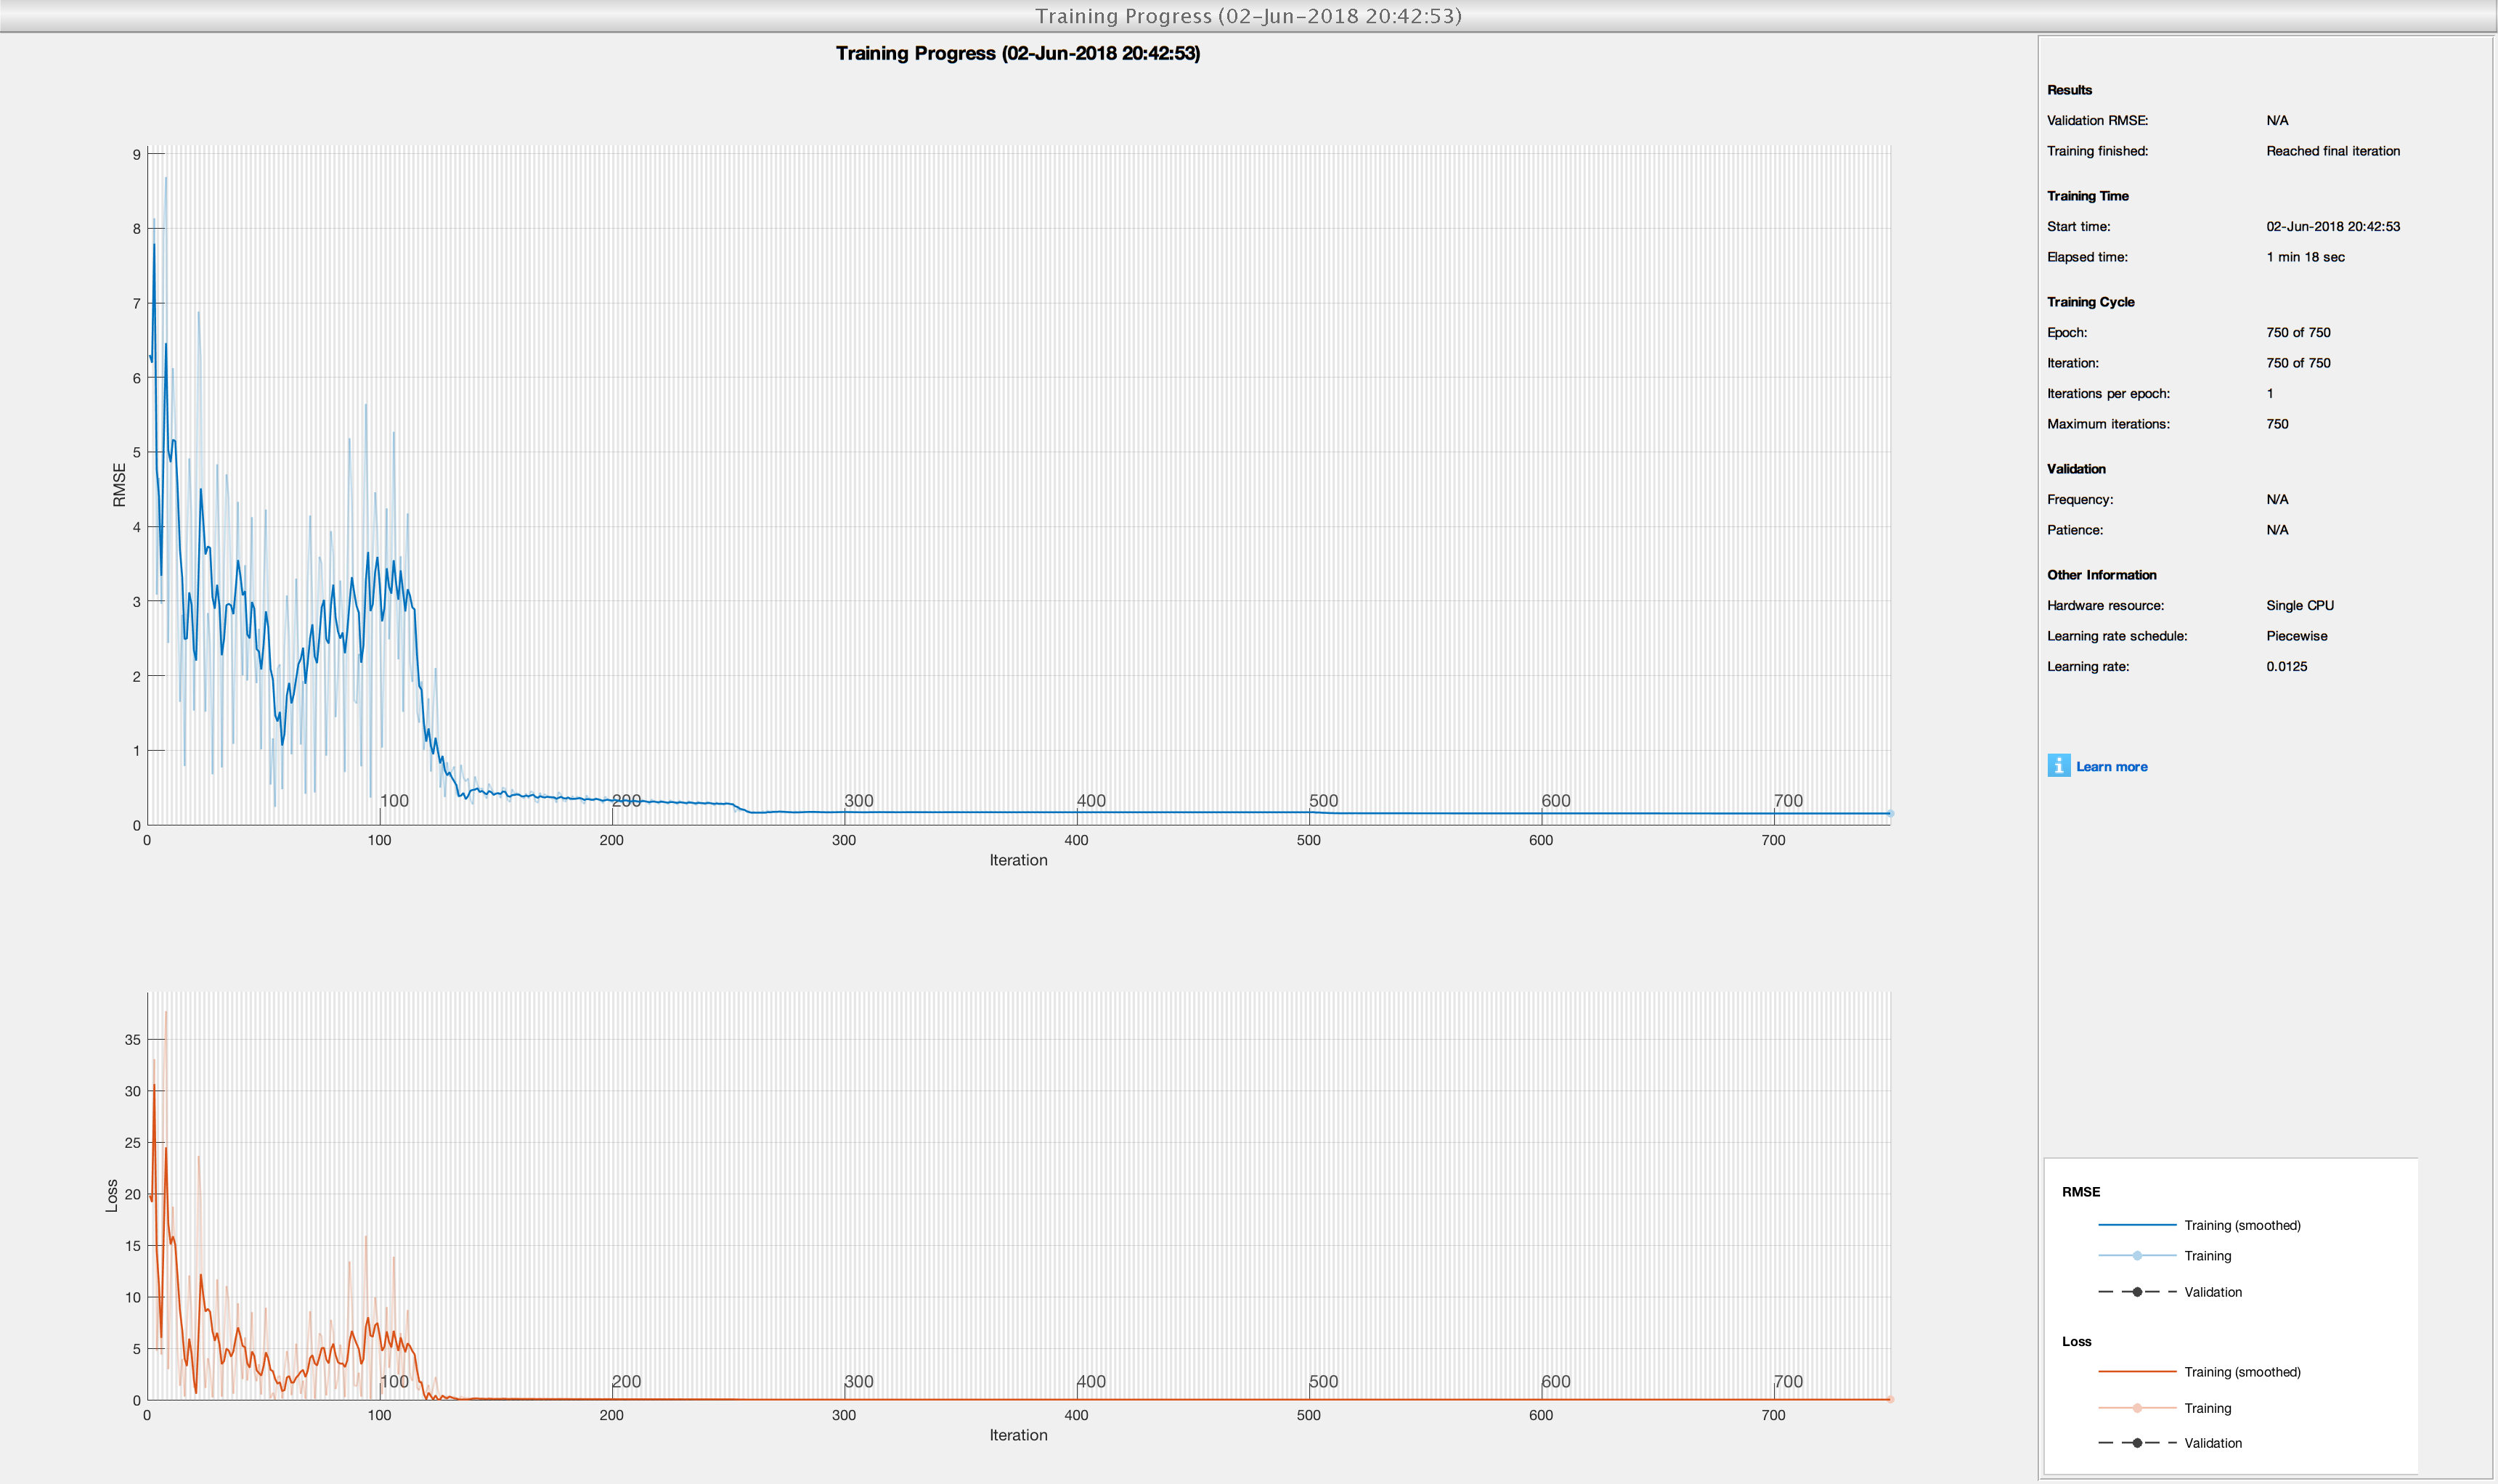

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         6.30 |         19.8 |          0.0500 |
|      50 |          50 |       00:00:07 |         3.14 |          4.9 |          0.0500 |
|     100 |         100 |       00:00:12 |         2.81 |          3.9 |          0.0500 |
|     150 |         150 |       00:00:18 |         0.42 |      8.6e-02 |          0.0500 |
|     200 |         200 |       00:00:23 |         0.30 |      4.4e-02 |          0.0500 |
|     250 |         250 |       00:00:28 |         0.28 |      4.0e-02 |          0.0500 |
|     300 |         300 |       00:00:34 |         0.17 |      1.4

net = trainNetwork(...
	XTrain, ...
	YTrain, ...
	layers2, ...
	opts);

## Predicting

net = predictAndUpdateState(net, XTrain);

YPred = [];

net = predictAndUpdateState(net, XTrain);
YPred = [];

numTimeStepsTest = length(XTest);

for i = 1:numTimeStepsTest
	[net, YPred(1, i)] = predictAndUpdateState(net, XTest(:, i));
end

net = predictAndUpdateState(net, XTrain);

% [net, YPred] = predictAndUpdateState(net, cache);

% for i = 2:numTimeStepsTest
% 	[net, YPred(1, i)] = predictAndUpdateState(net, YPred(1, i-1));
% end

% Unstandardize result
YPred = sig(1) * YPred + mu(1);

rmse = sqrt(mean(YPred - YTest) .^ 2);

YTrain = sig(1) * YTrain + mu(1);

## Visualize

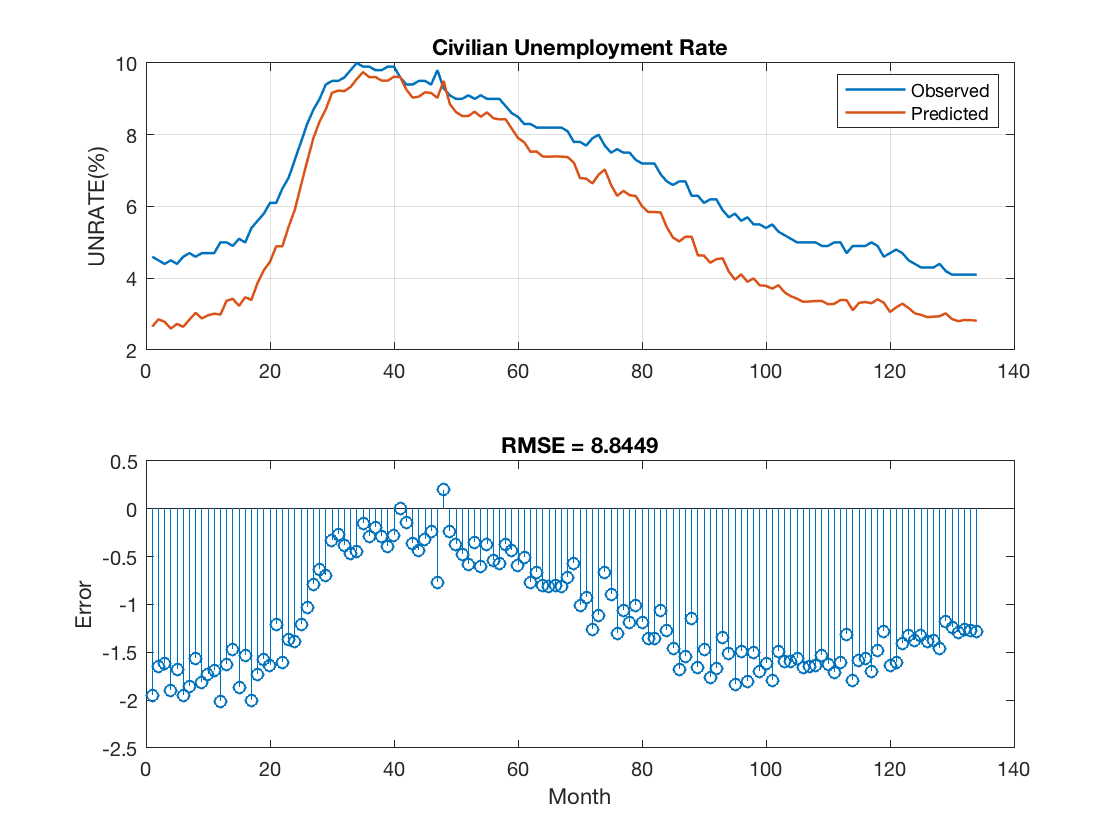

YPred = YPred - 5;
figure
subplot(2, 1, 1)
plot(YTest, "-", "LineWidth", 1.25)
hold on
plot(YPred, "-", "LineWidth", 1.25)
grid on
hold off
legend(["Observed" "Predicted"])
ylabel("UNRATE(%)")
title("Civilian Unemployment Rate")

subplot(2, 1, 2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)